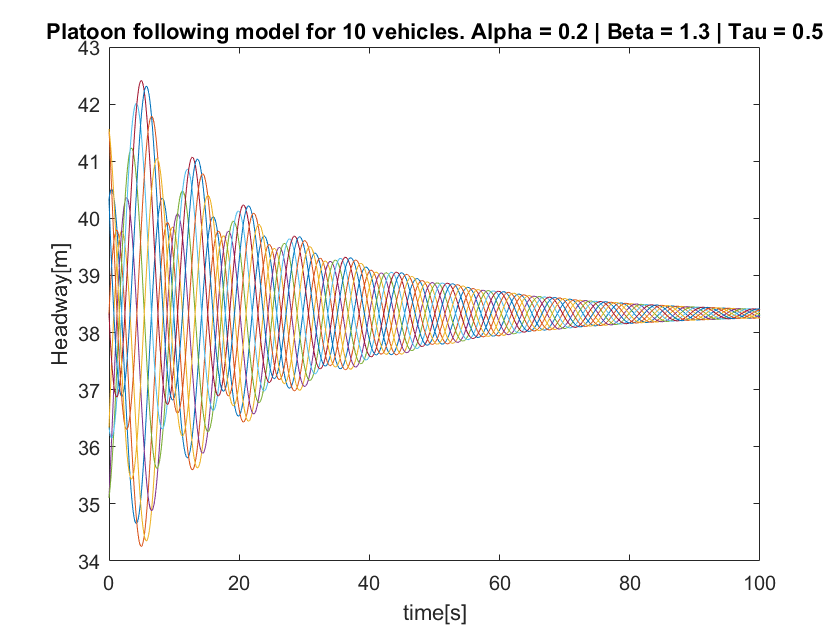


clear all; close all;

follow_num = 10;
tau = 0.5;

alpha = 0.2;
beta = 1.3;
kappa = 0.6;
k = 1;
A = 5;
omega = (alpha +2*beta)*tan(k*pi/follow_num);


vmax = 30;
vstar = 20;
a = 1;
b = 0.5;
hstop = 5;
hgo = hstop + vmax/kappa;
hstar = vstar/kappa + hstop;

tstart = 0;
tdelta = 0.1;
tend = 100;
tspan = tstart:tdelta:tend;

%Initial conditions
%Important quantity in ring conguration. Unlike platoon it will be different for each vehicle.

%Preallocating h0 and v0 for speed.
h0 = zeros(follow_num,1);
v0 = zeros(follow_num,1);
for i = 1:follow_num
  h0(i) = hstar + (A/omega)*(sin((2*k*pi/follow_num)*(i+1))-sin(2*k*pi*i/follow_num));  
end
for i = 1:follow_num
  v0(i) = vstar + A*cos(2*k*pi*i/follow_num);  
end
ic = @(t)[h0 v0];



sol = dde23(@(t,y,ytau)ddefun(t,y,ytau,follow_num,alpha,beta,kappa,vmax,hstop,hgo),tau,ic,tspan);
y = deval(sol,tspan);

headways = y(1:follow_num,:);
velocities = y(follow_num+1:2*follow_num,:);

figure(1);
plot(tspan,headways);
xlabel('time[s]');
ylabel('Headway[m]');
title("Platoon following model for "+follow_num+...
    " vehicles. Alpha = "+alpha+" | Beta = "+beta+" | Tau = "+tau);

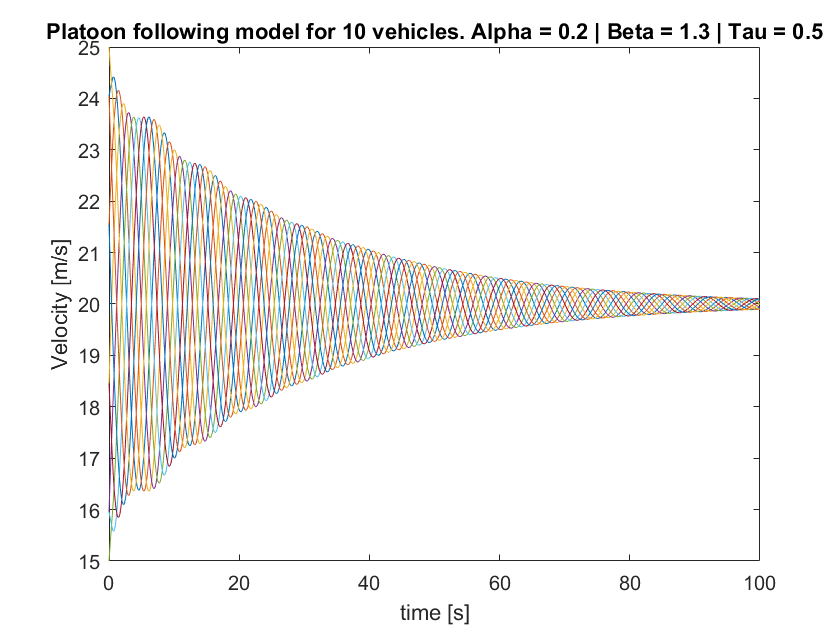


figure(2);
plot(tspan,velocities);
xlabel('time [s]');
ylabel('Velocity [m/s]');
title("Platoon following model for "+follow_num+...
    " vehicles. Alpha = "+alpha+" | Beta = "+beta+" | Tau = "+tau);

function dydt = ddefun(t,y,ytau,follow_num,alpha,beta,kappa,vmax,hstop,hgo)
    h = y(1:follow_num);
    vF = y(follow_num+1:end);
    vL = [vF(follow_num);
      vF(1:follow_num-1)] ;
  
    htau = ytau(1:follow_num);
    vFtau = ytau(follow_num+1:end);
    vLtau = [vFtau(follow_num);
          vFtau(1:follow_num-1)] ;
  
    %Range Policy
    Vh = 0 + ((hstop<h)&(h<hgo)).*(kappa.*(h-hstop)) + (h>=hgo).*(vmax);
    Vhtau = 0 + ((hstop<h)&(h<hgo)).*(kappa.*(htau-hstop)) + (h>=hgo).*(vmax);
    
    dydt = [(vL-vF);alpha.*(Vhtau-vF)+beta.*(vLtau-vFtau)];
end


